#  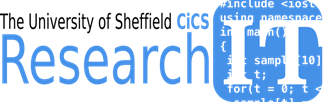                                      

# **Visualisation with Matlab**

## Outline

- overview

- program control structures

- scripts and functions

- Importing Data

- Data Types

# Overview

- course material

- matlab environment

- getting help

- vectors and matrices

- array indexing and operations

- simple plotting

# Review of Basic Graphics

# Importing Data and Pre-Processing Data

Inspect a set of data

edit ..\data\hurricaneData1990s.txt



Import data set and show scatter plot

hurrs=readtable('..\data\hurricaneData1990s.txt')

hurrs = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         01-Jul

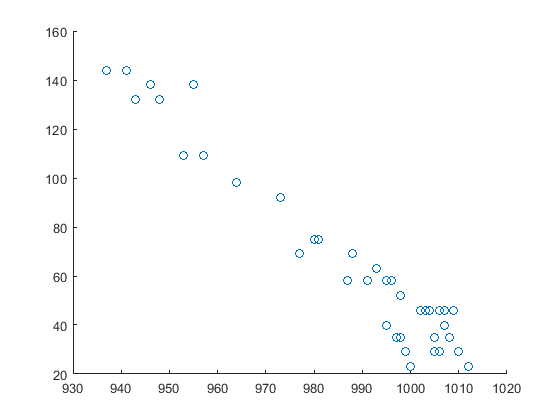

scatter(hurrs.Pressure,hurrs.Windspeed)

Import data set with header lines

hurrs2=readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5)

hurrs2 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         01-Ju

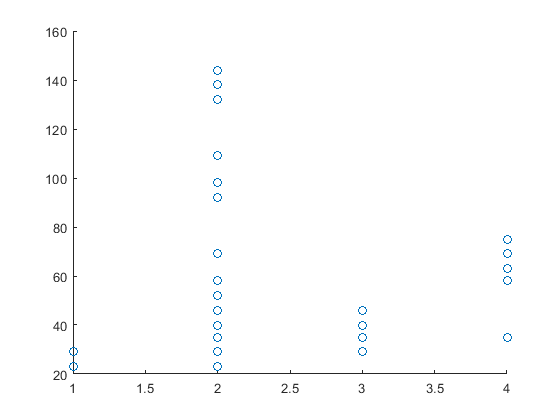

scatter(hurrs2.Number,hurrs2.Windspeed)

import data and skip lines with particular format ignore comment lines specify format

can alos specify particular delimeters

hurrs3=readtable('..\data\hurricaneData1990s-v3.txt','CommentStyle','##')

hurrs3 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         NaT  

scatter(hurrs3.Number,hurrs3.Windspeed)

x = readtable('..\data\hurricaneData1990s-v2.txt',...
      'Delimiter',',\t',...
      'HeaderLines',5);
  hurrs3

hurrs3 = 51×5 table
    Number         Timestamp              Country        Windspeed    Pressure
    ______    ____________________    _______________    _________    ________

    1         29-Jun-1991 12:00:00    'N/A'               23          1012    
    1         29-Jun-1991 18:00:00    'N/A'               23          1012    
    1         30-Jun-1991 00:00:00    'N/A'              NaN          1012    
    1         30-Jun-1991 06:00:00    'United States'     23          1012    
    1         30-Jun-1991 12:00:00    'United States'     23          1012    
    1         30-Jun-1991 18:00:00    'N/A'               23          1012    
    1         01-Jul-1991 00:00:00    'N/A'               23          1012    
    1         01-Jul-1991 06:00:00    'United States'     23          1012    
    1         NaT  


%    sz=size(hurrs3);
%   a=hurrs3.Country;
%   for i=1:sz(1)
%       if isequal(a{i},'N/A' )
%           hurrs3.Location{i} = 'Sea';
%       else
%           hurrs3.Location{i} = 'Land';
%       end
%   end
%   
%  hurrs3.Location;
   hurrs3.Country;

Categorical data

# cellfun

Apply function to each cell in cell arra

  %reports error in live script but gives correct output
  %in matlab workbench
      eqna = @(x)isequal(x,'N/A');
      setloc = @(x) char((x) .* 'Sea ' + ~(x) .* 'Land'); %setloc takes as input true or false
      hurrs3.Location=cellfun(eqna,hurrs3.Country); %the output hurrs2.Location is an array so use array function next
      hurrs3.Location=arrayfun(setloc,hurrs3.Location,'UniformOutput',false);

Categorical Data

  % convert country and location to categories
  %hurrs3.Country=categorical(hurrs3.Country);
   hurrs3.Location=categorical(hurrs3.Location);
   

C = hurrs3.Country;
whos C

  Name       Size            Bytes  Class    Attributes

  C         51x1              6332  cell               




% convert C to a categorical array

C = categorical(C);

whos C

  Name       Size            Bytes  Class          Attributes

  C         51x1               553  categorical              




%hurrs3.Country
  
 

rename categories

add a new variable named `Location` to the table `data`. This variable is meant to indicate whether the hurricane was observed on land or on the sea.

One way to do this is to find all the valid country names (values excluding 'N/A') and then merge them to create a new category named `'Land'` using the function `mergecats`. Assign the result to a new variable `Location`in the table `data`.

Then, use the function `renamecats` to rename the category `'N/A'` to `'Sea'`.



% Find the distinct categories
cats = categories(hurrs3.Country);

% Remove 'N/A' from cats
countryNames = setdiff(cats,'N/A');

% Merge all countries
hurrs3.Location = mergecats(hurrs3.Country,countryNames,'Land')

% Rename N/A to Sea
hurrs3.Location = renamecats(hurrs3.Location,'N/A','Sea') 

create a scatter plot with wind speed values along the x-axis and pressure values along the y-axis. Also, the observations on land should be plotted using red markers and the observations on sea should have blue markers. The plot should look something like this:

You can follow these steps to create the plot.

1. Find the wind speed and pressure values observed on land using the result of `data.Location` `==` `'Land'`as an index. Similarly, find values observed on the sea.

2. Use the `scatter``(``x``,``y``,``'b'``,``'filled'``)` command to create a scatter plot with filled blue markers. Replace `x`and `y` with windspeed and pressure values observed on the sea.

3. Use the command `hold` `on` so that the next plot is added on top of the existing plot.

4. Finally, create another scatter plot with values on land. Make this plot red (`'r'`). Enter `hold` `off` at the end.

% Read data
data = readtable('..\data\hurricaneData1990s-v2.txt','HeaderLines',5);
data.Country = categorical(data.Country);

% TODO - Add a new variable named 'Location' to the table 'data'
% It should be categorical  and have a value 'Land' if the row has a valid
% country listed and 'N/A' otherwise.


data = 51×6 table
    Number         Timestamp             Country       Windspeed    Pressure    Location
    ______    ____________________    _____________    _________    ________    ________

    1         29-Jun-1991 12:00:00    N/A               23          1012        Sea     
    1         29-Jun-1991 18:00:00    N/A               23          1012        Sea     
    1         30-Jun-1991 00:00:00    N/A              NaN          1012        Sea     
    1         30-Jun-1991 06:00:00    United States     23          1012        Land    
    1         30-Jun-1991 12:00:00    United States     23          1012        Land    
    1         30-Jun-1991 18:00:00    N/A               23          1012        Sea     
    1         01-Jul-1991 00:00:00    N/A               23       

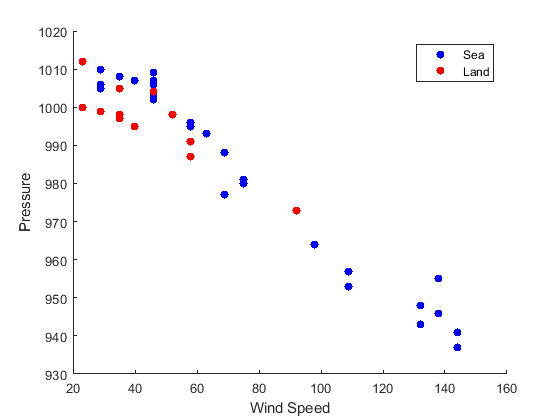

% Find the distinct categories
cats = categories(data.Country);

% Remove 'N/A' from cats
countryNames = setdiff(cats,'N/A');

% Merge all countries
data.Location = mergecats(data.Country,countryNames,'Land');

% Rename N/A to Sea
data.Location = renamecats(data.Location,'N/A','Sea')

% Find index of on-land and on-sea observation index
onland = data.Location == 'Land';
onsea = data.Location == 'Sea';


% Create scatter plots
scatter(data.Windspeed(onsea),data.Pressure(onsea),'b','filled');
hold on
scatter(data.Windspeed(onland),data.Pressure(onland),'r','filled');
hold off

% Optional - annotate the plot
xlabel('Wind Speed')
ylabel('Pressure')

ans = 1×4 categorical array
     last      mid      beg      beg 


legend('Sea','Land')




y = 1×9 categorical array
     small      huge      tiny      tiny      small      small      tiny      small      huge 


using categorical values

**Info:** If your categories have an inherent ordering – for example, “low”, “medium”, and “high” – you can specify this with an optional property `'Ordinal'`:

v = [ 10 5 0 0 ];
levels = { 'beg' 'mid' 'last' };
categorical(v,[0 5 10],levels)

x = [2 4 1 1 2 2 1 2 4];

c = 1×4 categorical array
     last      mid      beg      beg 


xlevels = {'tiny','small','big','huge'};

ans = 1×4 logical array
   1   0   0   0


y = categorical(x,1:4,xlevels)


y = 1×9 categorical array
     small      huge      tiny      tiny      small      small      tiny      small      huge 



%ordinal values

v = [ 10 5 0 0 ];
levels = { 'beg' 'mid' 'last' };
c = categorical(v,...
    [0 5 10],levels,...
    'Ordinal',true)

iSmall = 1×9 logical array
   1   0   0   0   1   1   0   1   0


 c > 'mid'
 
 y = categorical(x,1:4,xlevels,'Ordinal',true)
 

idx = 1×9 logical array
   1   1   0   0   1   1   0   1   1


 %Info: Categorical arrays allow the use of == for comparison.
y == 'tiny';

%Create a variable named iSmall which contains values of true 
% corresponding to the values in y that equal 'small'.

iSmall = y == 'small'

% Create a variable named idx which contains values 
% of true corresponding to the values in y that are larger than tiny.
idx = y > 'tiny'

Working with missing data

x = [0.32 0.95 NaN 0.87 0.71 0.42]

xAvg = mean(x)

% Info: In order to find the average value of a vector and omit NaN from the calculation,
% you can use the 'omitnan' flag as an additional input to the mean function.

xAvg = mean(x,'omitnan')
xMed = median(x,'omitnan')

% Info: There are some statistical functions, such as max and min, 
% that are designed to ignore NaNs in calculations by default.
xMin = min(x)
y=x
test = isequal(x,y)

% Info: The isequal function tests for strict equality, which means that NaNs
% will cause it to fail. However, if you wish to test an array for numeric equality,
%     as well as determining if the NaNs align, you can use isequaln.
test = isequaln(x,y)

The default behavior for many statistical functions is that `NaN` will be returned if the array includes `NaN`:

- [`cov`](http://www.mathworks.com/help/matlab/ref/cov.html)

- [`mean`](http://www.mathworks.com/help/matlab/ref/mean.html)

- [`median`](http://www.mathworks.com/help/matlab/ref/median.html)

- [`std`](http://www.mathworks.com/help/matlab/ref/std.html)

- [`var`](http://www.mathworks.com/help/matlab/ref/var.html)

However, the default behavior of [`max`](http://www.mathworks.com/help/matlab/ref/max.html) and [`min`](http://www.mathworks.com/help/matlab/ref/min.html) is to use `'omitnan'`.

zero values update

wsI=isnan(hurrs3.Windspeed);   
hurrs3.Windspeed(find(wsI))=0;


data = 51×7 table
    Number         Timestamp             Country       Windspeed    Pressure    Location      HurrCat  
    ______    ____________________    _____________    _________    ________    ________    ___________

    1         29-Jun-1991 12:00:00    N/A               23          1012        Sea         TD         
    1         29-Jun-1991 18:00:00    N/A               23          1012        Sea         TD         
    1         30-Jun-1991 00:00:00    N/A              NaN          1012        Sea         <undefined>
    1         30-Jun-1991 06:00:00    United States     23          1012        Land        TD         
    1         30-Jun-1991 12:00:00    United States     23          1012        Land        TD         
    1         3

% sz=size(hurrs3);
%   a=hurrs3.Country;
%   for i=1:sz(1)
%       if isequal(a{i},'N/A' )
%           hurrs3.Location{i} = 'Sea';
%       else
%           hurrs3.Location{i} = 'Land';
%       end
%   end

## Discretizing Continuous Data

discretize the values in `price` into 4 bins.

As a first step, create a row vector, `levels`, that contains the edge values of the desired bins. The lowest edge value should be `0`, the highest should be `40` and difference between the adjacent edge values should be `10`

price = [34.17,26.71,7.92,27.17,36.30,24.88,30.34,27.26,16.96];
levels = 0:10:40

% Info: You can use the discretize function to categorize
% values into discrete bins using the values of the bin edges.
% Bin the values in the price vector using levels as the 
% bin edges. Store the resulting bin numbers in pBinNo.
pBinNo = discretize(price,levels)

% Discretize x using the bin edges binedges 
% and store the resulting bin numbers in y.
binedges = [0 0.2 0.6 0.9];
x = [ 0.90 0.32 0.95 NaN 0.87 0.71 0.42 0.60];
y = discretize(x,binedges)

% Info: Any NaNs or values outside the range of the bins
% are unclassified.
% 
% If you want to include bins for values outside of the edges, 
% add -Inf or Inf to the vector of bin edges.
% Update binedges so that there is one more category that extends 
% the range to infinity.

binedges = [0 0.2 0.6 0.9 Inf]

% create a variable named y which contains the bin number
% for each value in x.
y = discretize(x,binedges)

% Info: By default, the bins are returned as numeric values.
% To discretize data into categories, use the Categorical option.
binedges = [0 0.2 0.6 0.9 Inf];
x = [ 0.90 0.32 0.95 NaN 0.87 0.71 0.42 0.60];
cnm = {'red','green','blue','black'};

y = discretize(x,binedges,'Categorical',cnm)


% Info: Because the categories are based on a numeric scale, 
% the resulting categorical array is ordinal. Thus, one category 
% can be greater than another.
% Now create a variable named leGreen that contains the number of 
% values in y that are less than or equal to 'green'.
leGreen = nnz(y <= 'green')

## Discretizing the hurricane data

**Info:** The Saffir-Simpson hurricane scale bin edges are stored in `SSscale`. Each bin corresponds to a hurricane category identified by the `catnames`variable.

% create a new variable named data.HurrCat that contains the 
% hurricane category of the observation based on data.Windspeed.
SSscale = [0 39 74 96 111 130 157 Inf];
catnames = {'TD','TS','1','2','3','4','5'};
data.HurrCat = discretize(data.Windspeed,SSscale,'Categorical',catnames)


# Review of Basic Graphics